# SELEX7620 Lab 5

Name:  Taewoo Kim, A01284763, and set T

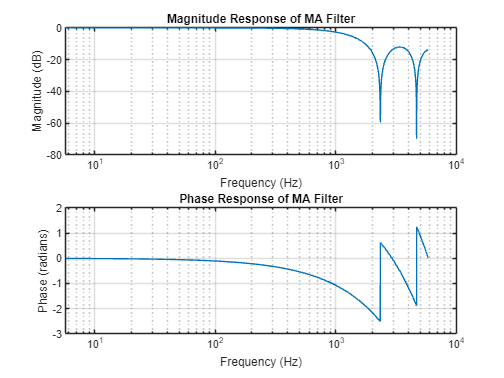

M = 4;                   % MA filter size
b = ones(1, M+1) / (M+1); % MA filter coefficients
a = 1;                   % denominator coefficient for FIR filter
Fs = 11700;               % sampling frequency

[H, f] = freqz(b, a, 1024, Fs); % compute the frequency response

% Plot magnitude response
figure;
subplot(2,1,1);
semilogx(f, 20*log10(abs(H)));
grid on;
xlabel('Frequency (Hz)');
ylabel('Magnitude (dB)');
title('Magnitude Response of MA Filter');

% Plot phase response
subplot(2,1,2);
semilogx(f, angle(H));
grid on;
xlabel('Frequency (Hz)');
ylabel('Phase (radians)');
title('Phase Response of MA Filter');


% Use fvtool for a detailed view
fvtool(b, a, 'Fs', Fs);

% Find -3dB cutoff frequency
mag = abs(H);
mag_dB = 20*log10(mag);
cutoff_idx = find(mag_dB <= -3, 1, 'first');
cutoff_freq = f(cutoff_idx);

% Find null frequencies (frequencies where magnitude response is zero)
null_idxs = find(abs(H) < 1e-3); % Close to zero
null_freqs = f(null_idxs);

% Display results
fprintf('3dB Cutoff Frequency: %.2f Hz\n', cutoff_freq);

3dB Cutoff Frequency: 1056.88 Hz


fprintf('Null Frequencies: %.2f \n', null_freqs);

Null Frequencies: 4678.86 


Waveform measurements

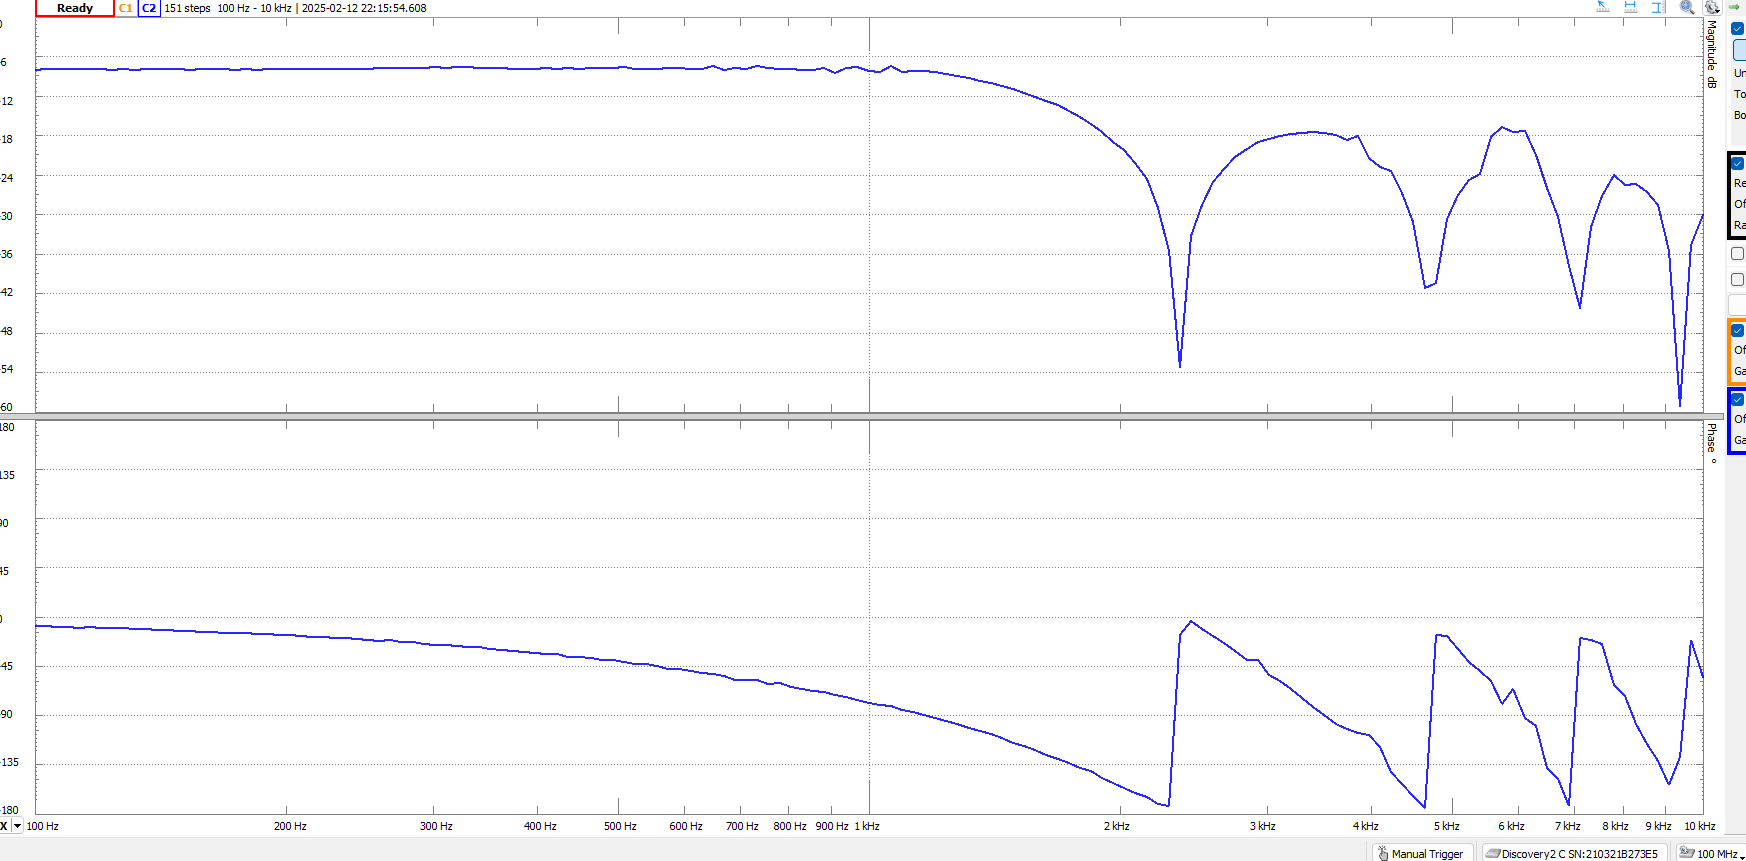

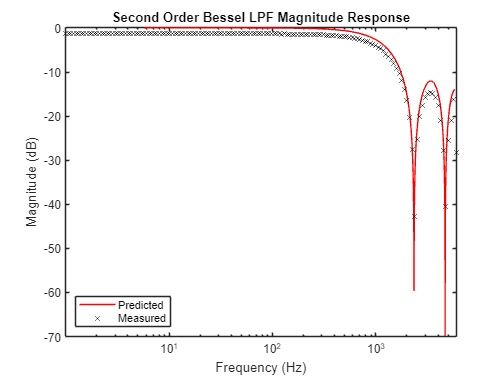

% Read table from the csv file
measured = readtable('FIR.csv', 'VariableNamingRule', 'preserve');
% 
% % Extract all the values
meas_freq = measured.("Frequency (Hz)");
meas_mag_dB = measured.("Channel 2 Magnitude (dB)");
meas_phase = measured.("Channel 2 Phase (deg)");
mag_dB = 20*log10(abs(H));

figure(2)
clf
semilogx(f,mag_dB,'r-',meas_freq,meas_mag_dB,'kx')
xlabel('Frequency (Hz)')
xlim([0, 6000])
ylabel('Magnitude (dB)')
title('Second Order Bessel LPF Magnitude Response')
legend('Predicted', 'Measured', 'Location', 'southwest');